clear
clf

load('data/gauntlet_scans.mat')
warning('off','all')

r = r_all(:,4);
theta = theta_all(:,4);

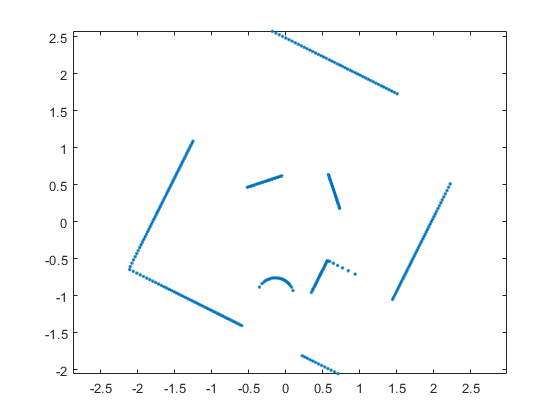

r_clean_index = find((r ~= 0) & (r < 3));
r_clean = r(r_clean_index);
theta_clean = theta(r_clean_index);
[x, y] = pol2cart(theta_clean, r_clean);
points = [x y];
clf
plot(x, y, '.')
axis equal

% find lines
d = 0.01

d = 0.0100

n = 500

n = 500

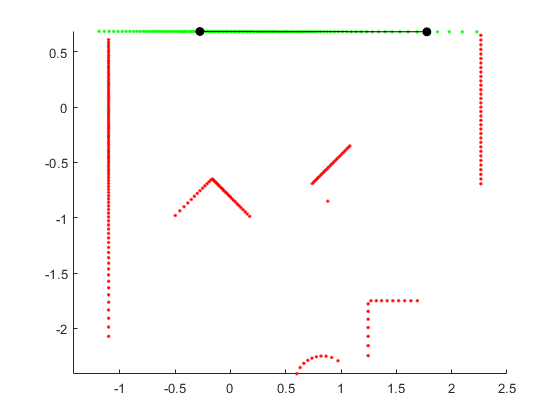

[endpoints, inliers1, outliers1, m, b] = ransac_line_fit(points, d, n, 1);

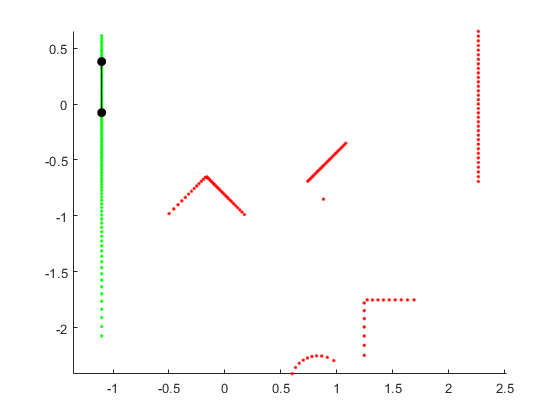

[endpoints, inliers2, outliers2, m, b] = ransac_line_fit(outliers1, d, n, 1);

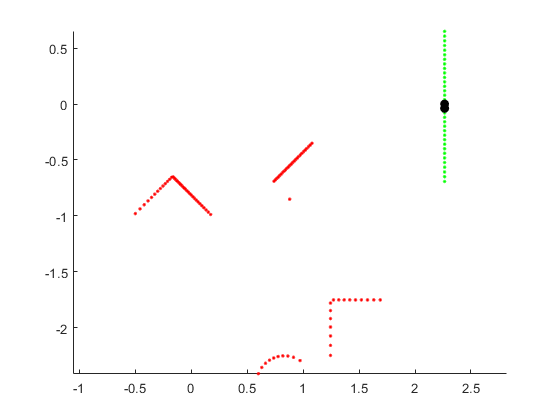

[endpoints, inliers3, outliers3, m, b] = ransac_line_fit(outliers2, d, n, 1);

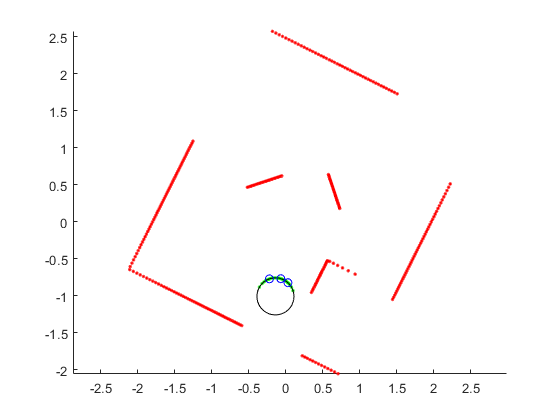

d = 0.01;
n = 5000;
r_max = 0.3;
[endpoints, inliers4, outliers4, near_matches4, center, rad] = ransac_circle_fit(points, r_max, d, n, 1);

remainders = outliers4;

d = 0.01

d = 0.0100

n = 1000

n = 1000

endpoints = 2×2 single matrix
   -0.0654   -0.7473
    1.2451   -1.9925


inliers = 27×2 single matrix
   -0.1758   -0.6559
   -0.1622   -0.6505
   -0.1524   -0.6603
   -0.1425   -0.6703
   -0.1323   -0.6805
   -0.1218   -0.6909
   -0.1111   -0.7016
   -0.1001   -0.7126
   -0.0889   -0.7239
   -0.0773   -0.7354


remainders = 54×2 single matrix
   -0.4988   -0.9789
   -0.4571   -0.9373
   -0.4195   -0.8997
   -0.3853   -0.8655
   -0.3541   -0.8343
   -0.3255   -0.8057
   -0.2991   -0.7793
   -0.2748   -0.7549
   -0.2522   -0.7323
   -0.2311   -0.7113


m = single
1.8259

b = single
-0.6280

endpoints = 2×2 single matrix
    0.9753   -0.4548
    0.7525   -0.6776


inliers = 26×2 single matrix
    0.7400   -0.6901
    0.7525   -0.6776
    0.7650   -0.6650
    0.7776   -0.6525
    0.7902   -0.6399
    0.8028   -0.6272
    0.8155   -0.6145
    0.8283   -0.6018
    0.8411   -0.5890
    0.8540   -0.5760


remainders = 28×2 single matrix
   -0.4988   -0.9789
   -0.4571   -0.9373
   -0.4195   -0.8997
   -0.3853   -0.8655
   -0.3541   -0.8343
   -0.3255   -0.8057
   -0.2991   -0.7793
   -0.2748   -0.7549
   -0.2522   -0.7323
   -0.2311   -0.7113


m = single
0.1558

b = single
-0.6067

endpoints = 2×2 single matrix
   -0.4195   -0.8997
   -0.4571   -0.9373


inliers = 12×2 single matrix
   -0.4988   -0.9789
   -0.4571   -0.9373
   -0.4195   -0.8997
   -0.3853   -0.8655
   -0.3541   -0.8343
   -0.3255   -0.8057
   -0.2991   -0.7793
   -0.2748   -0.7549
   -0.2522   -0.7323
   -0.2311   -0.7113


remainders = 16×2 single matrix
    1.2451   -2.2462
    1.2451   -2.1565
    1.2451   -2.0721
    1.2451   -1.9172
    1.2451   -1.8459
    1.2451   -1.7781
    1.2714   -1.7499
    1.3187   -1.7499
    1.3672   -1.7499
    1.4171   -1.7499


m = single
0.0784

b = single
-0.8668

endpoints = 2×2 single matrix
    1.4684   -1.7499
    1.5756   -1.7499


inliers = 9×2 single matrix
    1.2714   -1.7499
    1.3187   -1.7499
    1.3672   -1.7499
    1.4171   -1.7499
    1.4684   -1.7499
    1.5212   -1.7499
    1.5756   -1.7499
    1.6318   -1.7499
    1.6899   -1.7499


remainders = 7×2 single matrix
    1.2451   -2.2462
    1.2451   -2.1565
    1.2451   -2.0721
    1.2451   -1.9172
    1.2451   -1.8459
    1.2451   -1.7781
    0.8801   -0.8499


m = single
-1.7039e-06

b = single
-1.7499

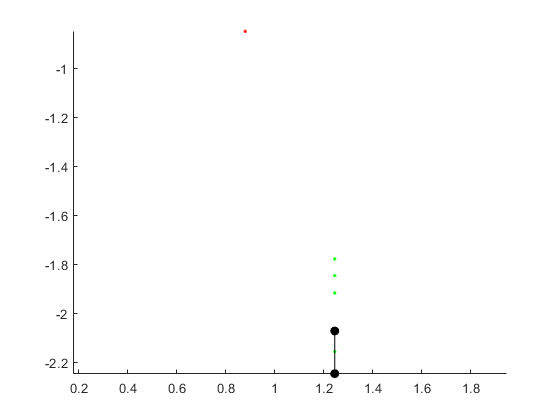

endpoints = 2×2 single matrix
    1.2451   -2.2462
    1.2451   -2.0721


inliers = 6×2 single matrix
    1.2451   -2.2462
    1.2451   -2.1565
    1.2451   -2.0721
    1.2451   -1.9172
    1.2451   -1.8459
    1.2451   -1.7781


remainders = 1×2 single row vector
    0.8801   -0.8499


m = single
-0.0498

b = single
-2.1841


while length(remainders) >= 3
    [endpoints, inliers, remainders, m, b] = ransac_line_fit(remainders, d, n, 1)
end